Definicja układu Lurie:

% Część liniowa
G = tf([2 1], [1  4 6 4 1]);
%G = tf(1, [1 -0.1]);

% Część nieliniowa
fi = @(y)tanh(y);

Sprawdzenie czy część liniowa spełnia warunki kryterium Popova

if (~isstable(G))
    % Niespełniony
    % Szukamy h stabilizującego
    [r, krl] = rlocus(G);
    for i = 1:size(krl, 2)
        if (all(r(:, i) < 0))
            h = krl(:, i);
            break;
        end
    end
    % Modyfikacja układu
    Ga = feedback(G, h);
    fi_a = @(y)(fi(y) - h*y);
else
    % Spełniony
    Ga = G;
    fi_a = fi;
end

Charakterystyka nieliniowości

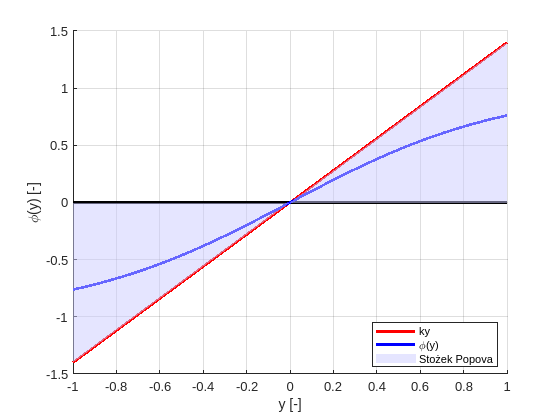

k = 1.4;

y = -1:0.01:1;
fi_plot = fi_a(y);
k_plot = k * y;
zero_plot = zeros(size(k_plot));

figure();
grid on;
hold on;
xlabel("y [-]");
ylabel("\phi(y) [-]");
legend("show", "Location", "best");
plot(y, k_plot, "r", "LineWidth", 2, "DisplayName", "ky");
plot(y, zero_plot, "k", "LineWidth", 2, "HandleVisibility", "off");
plot(y, fi_plot, "b", "LineWidth", 2, "DisplayName", "\phi(y)");
% Zaznacz obszar Popova
fill([y fliplr(y)], [zero_plot fliplr(k_plot)], ...
     [0.8 0.8 1], 'EdgeColor', 'none', 'FaceAlpha', 0.5, "DisplayName", "Stożek Popova");

Charakterystyka Popova i prosta związana z sektorem:

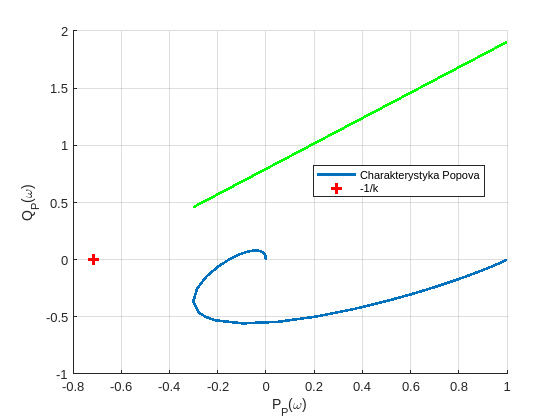

[p, q, wout] = nyquist(Ga);

pp = squeeze(p);
qp = squeeze(q) .* wout;

figure();
grid on;
hold on;
legend("show", "Location", "best");
xlabel("P_P(\omega)");
ylabel("Q_P(\omega)");
plot(pp, qp, "LineWidth", 2, "DisplayName", "Charakterystyka Popova");

plot(-1/k, 0, "r+", "MarkerSize", 8, "LineWidth", 3, "DisplayName", "-1/k");
alpha = 0.9;
pv = 1/alpha * (pp + 1/k);
plot(pp, pv, "g", "LineWidth", 2, "HandleVisibility", "off");

Przebiegi układu sterowania:

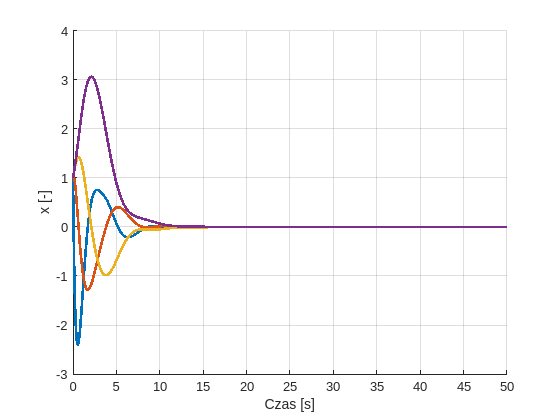

[A, B, C, ~] = tf2ss(G.Numerator{1}, G.Denominator{1});

% funkcja do ode45
system = @(t,x)(A*x - B*fi(C*x));

[t, y] = ode45(system, [0, 50], ones(size(B)));

figure();
grid on;
hold on;
xlabel("Czas [s]");
ylabel("x [-]");
plot(t, y, "LineWidth", 2);